% Problem 1
clc
clearvars

% initial position
x_0 = 0;
y_0 = 0;
z_0 = 0;

% initial velocity
vx_0 = 0;
vy_0 = 58.12*cosd(45);
vz_0 = 58.12*sind(45);

% pack initial condidtions into column vector
init = [x_0 vx_0 y_0 vy_0 z_0 vz_0]';

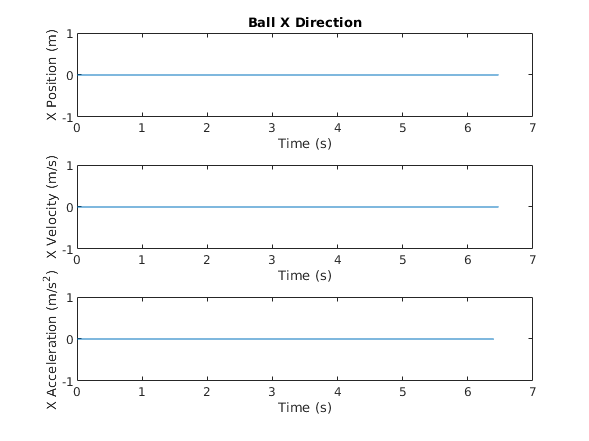

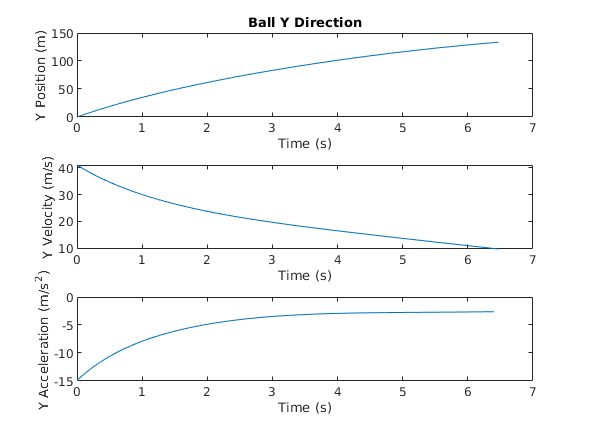

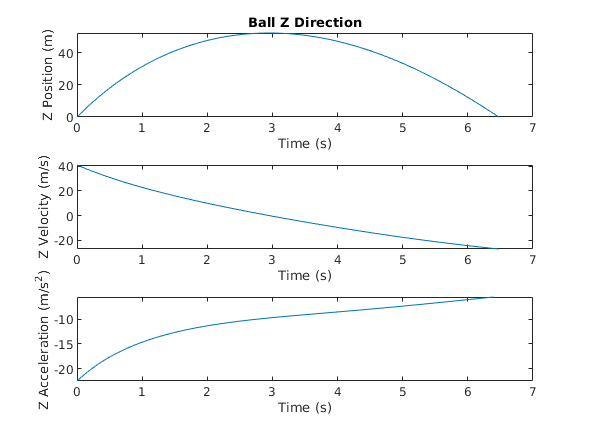

final_x = 0

final_y = 133.5839

final_z = -1.3785e-12

% 15 mph headwind

% wind vector
w = [0 -6.7 0]';

% call ode and solve for time and position
[t,p] = projectile(init,w);
graphprojectile(t,p)

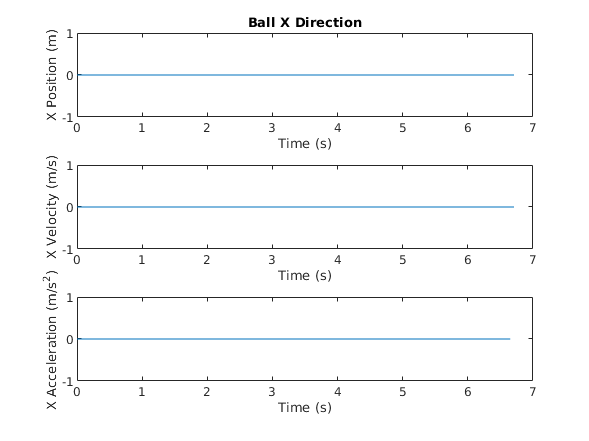

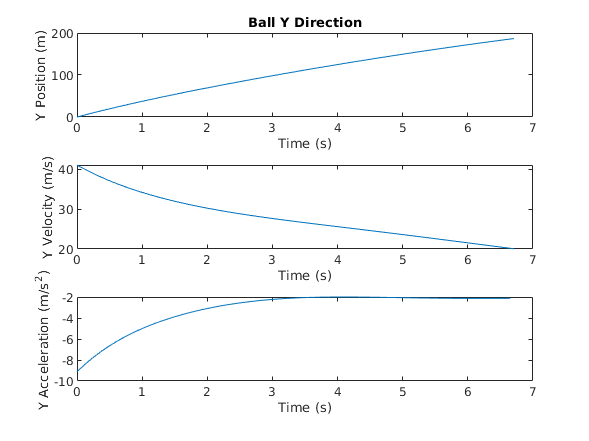

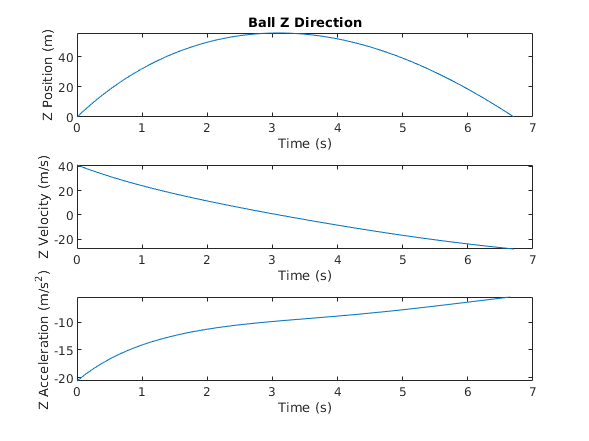

final_x = 0

final_y = 186.8279

final_z = -7.9936e-15

% 15 mph tailwind

% wind vector
w = [0 6.7 0]';

% call ode and solve for time and position
[t,p] = projectile(init,w);
graphprojectile(t,p)

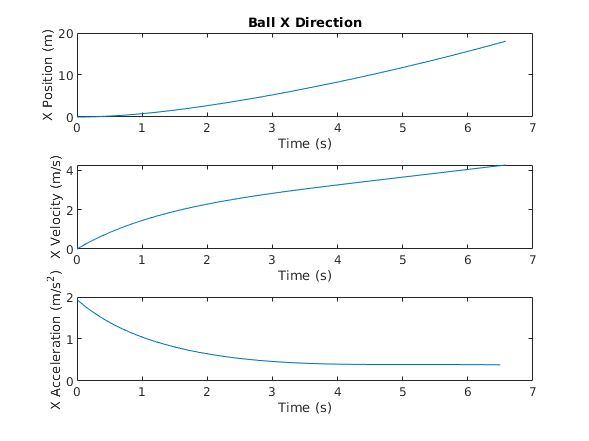

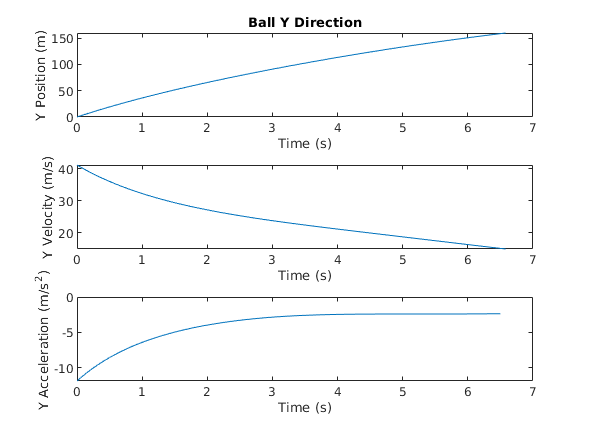

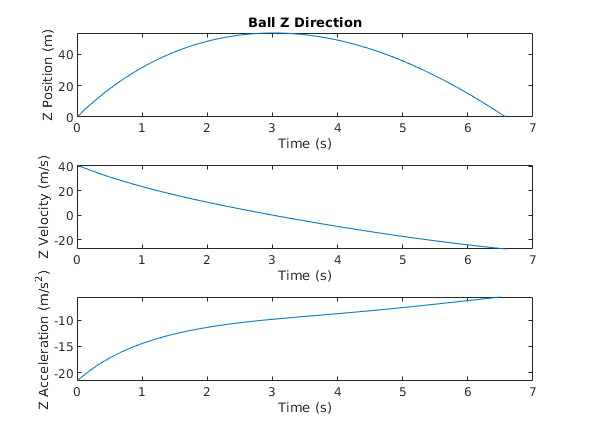

final_x = 18.0442

final_y = 159.7407

final_z = -1.5667e-12

% 15 mph side wind

% wind vector
w = [6.7 0 0]';

% call ode and solve for time and position
[t,p] = projectile(init,w);
graphprojectile(t,p)

function [t,p] = projectile(init,w)

        tspan = [0:.05:10];
        
        rho = 1.29; % kg/m^3
        Cd = 0.25;
        D = 0.0427; % m
        
        m = 0.0459; % kg
        c = (pi*rho*Cd*D^2)/8;
        g = 9.8; % m/s^2
        
        % wind vector m/s
        
        options = odeset('Events', @eventFcn);
        [t,p] = ode45(@f,tspan,init,options);


    function dpdt = f(~,p)
        
        % magnitude of velocity with respect to wind
        V = sqrt((p(2)-w(1))^2+(p(4)-w(2))^2+(p(6)-w(3))^2);
        
        xv = p(2);
        xa = -c/m*(p(2)-w(1))*V;
        yv = p(4);
        ya = -c/m*(p(4)-w(2))*V;
        zv = p(6);
        za = -c/m*(p(6)-w(3))*V - g;
        
        dpdt = [xv xa yv ya zv za]';
    end

    function [position,isterminal,direction] = eventFcn(~,p)
        position = p(5); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end

function graphprojectile(t,p)
    x = p(:,1);
    v_x = p(:,2);
    a_x = diff(v_x(1:end-1))/.05;
    y = p(:,3);
    v_y = p(:,4);
    a_y = diff(v_y(1:end-1))/.05;
    z = p(:,5);
    v_z = p(:,6);
    a_z = diff(v_z(1:end-1))/.05;


    figure
    subplot(3,1,1)
    plot(t,x)
    xlabel("Time (s)")
    ylabel("X Position (m)")
    title("Ball X Direction")
    subplot(3,1,2)
    plot(t,v_x)
    xlabel("Time (s)")
    ylabel("X Velocity (m/s)")
    subplot(3,1,3)
    plot(t(1:end-2),a_x)
    xlabel("Time (s)")
    ylabel("X Acceleration (m/s^2)")
    
    figure
    subplot(3,1,1)
    plot(t,y)
    xlabel("Time (s)")
    ylabel("Y Position (m)")
    title("Ball Y Direction")
    subplot(3,1,2)
    plot(t,v_y)
    xlabel("Time (s)")
    ylabel("Y Velocity (m/s)")
    subplot(3,1,3)
    plot(t(1:end-2),a_y)
    xlabel("Time (s)")
    ylabel("Y Acceleration (m/s^2)")
    
    figure
    subplot(3,1,1)
    plot(t,z)
    xlabel("Time (s)")
    ylabel("Z Position (m)")
    title("Ball Z Direction")
    subplot(3,1,2)
    plot(t,v_z)
    xlabel("Time (s)")
    ylabel("Z Velocity (m/s)")
    subplot(3,1,3)
    plot(t(1:end-2),a_z)
    xlabel("Time (s)")
    ylabel("Z Acceleration (m/s^2)")
    
    final_x = x(end)
    final_y = y(end)
    final_z = z(end)
end